clc; clear
addpath('R:\jwu123\E map and MATLAB functions\MATLAB files')
addpath('R:\jwu123\E map and MATLAB functions')
E_map=dlmread('E_Map_MaskV2CC1200_100V_3Dmap_all6on.txt');

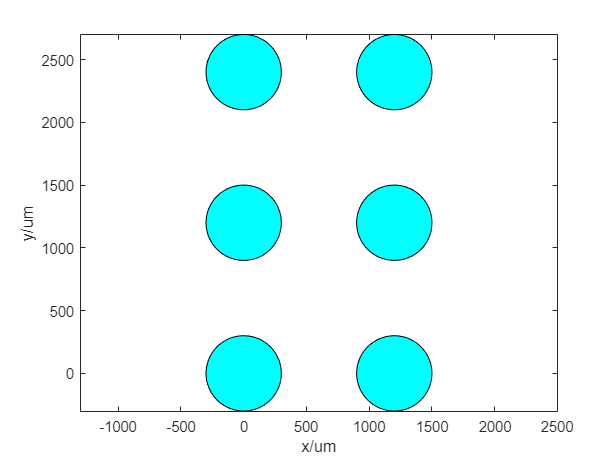

%%
Lx = 1200 ;%um
Ly = 1200 ;% um
nooc = 2;
noor = 3;

% % Oil parameter
% e0 = 8.85*10^-12;%F/(m)
% em = 2.17*e0;
% mu =  251.16*10^(-3)*0.8638;

% Water parameter
mu =  1;
e0 = 8.85*10^-12;%F/(m)
em = 80.1*e0;

% plot the board
padR = 300;% um
chipX = Lx * nooc;
chipY = Ly * noor;
h = plotChip(chipX,chipY,padR,nooc,noor);
hold on

%%p

%E_map = dlmread('E_Map_4by4_100V_CC400_TopElectrode_3D_750um.txt');
data = dlmread('G:\Jiaxu Song\Ag_in_warter\test2\test2_data.txt'); % Load data here
No_wires = 1;
x = data(1:end,1);
y = data(1:end,2);
z = data(1:end,3);
% U(:,17) = table2array(data(1:178,22));
U = data(1:end,5:10);
U = U'./10000;
N = length(z);
% time = table2array(data(1:178,2));
dt = 0.1;

% for ii = 1:No_wires
%     plot3(X(:,ii),Y(:,ii),Z,'b-','LineWidth',1)
%     hold on
%     plot3(X(1,ii),Y(1,ii),Z(1),'o','LineWidth',1)
% end

axis equal
xlabel('x/um')
ylabel('y/um')


%%
% k=1;
% time = 0;
% x_plot = X(1,:);
% y_plot = Y(1,:);
% z_plot = ones(1,No_wires)*Z(1);
% height(1,:) = ones(1,No_wires)*Z(1);
% for kk =2:N
%
%     for jj = 1:No_wires
%         if flag(kk) == jj-1
%             height(kk,jj) = Z(kk);
%         else
%             height(kk,jj) = height(kk-1,jj);
%         end
%     end
%
%     if flag(kk) ~= flag(kk-1)
%
%         time = [time, (kk-1)*0.1];
%         x_plot = [x_plot;X(kk-1,:)];
%         y_plot = [y_plot;Y(kk-1,:)];
%         z_plot = [z_plot;height(kk-1,:)];
%     end
% end
% figure
% for ii = 1:No_wires
%     plot3(x_plot(:,ii),y_plot(:,ii),z_plot(:,ii),'b-','LineWidth',1)
%     hold on
%     plot3(x_plot(1,ii),y_plot(1,ii),z_plot(1,ii),'o','LineWidth',1)
%
% end
% axis equal
% xlabel('x/um')
% ylabel('y/um')


%%
gx=0:10:1200; % grid size same as the E map
gy=0:10*2:1200*2;
gz=0:1:120;
% nn = length(z_plot);
% index = [1 int16(time(2:end)/0.1)];
u = U';
k = 1;
Zeta = [];
p_sim(:,1) = [x(1);y(1)];
EF_new_save = [];
EF_save = [];
for ii = 1:N-1

    E = [];
    px = x(ii);
    py = y(ii);
    pz = z(ii);

    for j=1:6*3   %51%48
        g=reshape(E_map(:,j),[121,121,121]);
        intE =interp3(gx,gy,gz,g,px,py,pz);
        E(:,j)=intE(:);
    end

    %EF=[E(1,1:17);E(1,18:34);E(1,35:51)];
    EF=[E(1,1:6);E(1,7:12);];
    Ef_save = [E(1,1:6);E(1,7:12);E(1,13:18)];

    B = em*EF/mu*10^6;
    EF_save = [EF_save Ef_save*U(:,ii)]; % Exierimental Electric field
    
    p_sim(:,ii+1) = p_sim(:,ii)+B*U(:,ii)*dt;

end


c=[1]; % initial guess of zeta values, 1 zeta or 2 zeta?
options=optimset('fminsearch');
options.TolX=0.001;
options.Display='off';
p_sim_new(:,1) = p_sim(:,1);

p_simx = p_sim(1,:); p_simy = p_sim(2,:);

[zeta,sfval,sexit,soutput]=fminsearch(@fun,c,options,p_simx,p_simy,x',y');



%% use the zeta value to calculate the simulated trajectories
for ii = 1:N-1

    E = [];
    px = p_sim_new(1,ii);
    py = p_sim_new(2,ii);
    pz = z(ii);

    for j=1:6*3   %51%48
        g=reshape(E_map(:,j),[121,121,121]);
        intE =interp3(gx,gy,gz,g,px,py,pz);
        E(:,j)=intE(:);
    end

    %EF=[E(1,1:17);E(1,18:34);E(1,35:51)];
    EF=[E(1,1:6);E(1,7:12);];
    Ef_save = [E(1,1:6);E(1,7:12);E(1,13:18)]; 
    B = em*EF/mu*10^6;
    
    p_sim_new(:,ii+1) = p_sim_new(:,ii)+diag(zeta)*B*U(:,ii)*dt;


    EF_new_save = [EF_new_save Ef_save*U(:,ii)]; % simulated electric field

end


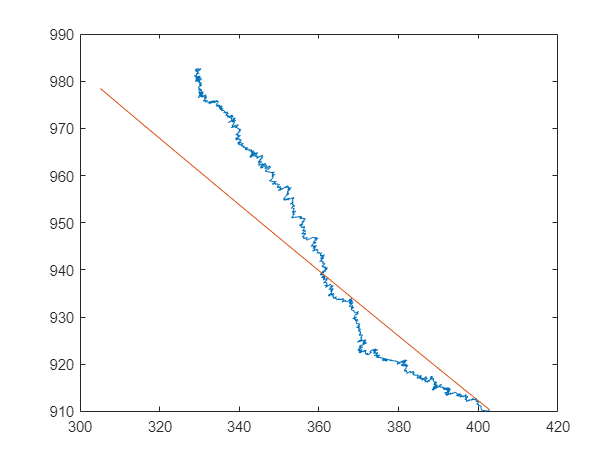


figure(1)
plot(x,y); hold on;
plot(p_sim_new(1,:),p_sim_new(2,:)); hold off



%%
% figure
% for ii = 1:No_wires
%     plot3(x_plot(:,ii),y_plot(:,ii),z_plot(:,ii),'b-','LineWidth',1)
%     hold on
%     plot3(x_plot(1,ii),y_plot(1,ii),z_plot(1,ii),'o','LineWidth',1)
%     plot3(p_simx_new(ii,:),p_simy_new(ii,:),p_simz_new(ii,:),'--','LineWidth',1)
% end
% xlabel('x/um')
% ylabel('y/um')
angle = data(:,4);
zeta_out = ones(N,1)*zeta;
a = EF_save;
a(:,end+1) = a(:,end);

EF_new_save(:,end+1) = EF_new_save(:,end);

data_out = [x,y,z,p_sim_new',z,a',EF_new_save',angle,zeta_out];

csvwrite('G:\Jiaxu Song\Ag_in_warter\test2\test2_output.csv',data_out);